# Cross-Validation

## Loading

clear all; 
load('../1-Cleaning/data/dc_corr.mat'); 
load('./data/Flight_inference.mat'); 
addpath('functions\')
dclat = [dc.lat]'; dclon = [dc.lon]'; dcname={dc.name};
clear dc

## Build the distance matrix (sparse)

Build the covariance function from the distance

Ddist_sm = squareform(pdist([dclat dclon], @lldistkm));

D=table();
for i_t=1:numel(unique(data.day))
    id = find(data.day==i_t);
    d = table();
    d.Ddist = reshape(Ddist_sm(data.radar(id),data.radar(id)),[],1);
    d.Dtime = reshape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),1);
    d.Did2 = repelem(id,numel(id));
    D=[D ; d];
end

## Estimate u (E-W)

Estimate the value removing all values of the radar.

Cu = sparse(D.Did1,D.Did2, uv.cov.Cu(D.Ddist, D.Dtime));

ccuv.ut_est=nan(size(uv.ut));
ccuv.ut_sig=nan(size(uv.ut));

for i_t=1:numel(unique(data.day))
    id_t= find(i_t==data.day);
    for i_r=1:numel(unique(data.radar))
        
        id_r = i_r==data.radar(id_t);
    
        Lambda = Cu(id_t(~id_r),id_t(~id_r))\Cu(id_t(~id_r),id_t(id_r));
        
        ccuv.ut_est(id_t(id_r)) = Lambda' * uv.ut(id_t(~id_r));
        ccuv.ut_sig(id_t(id_r)) = sqrt(sum(uv.cov.parm_u(1:2)) - sum(Lambda.*Cu(id_t(~id_r),id_t(id_r))));
    end
end

clear Cu

## Estimate v (N-S)

Estimate the value removing all values of the radar.

Cv = sparse(D.Did1,D.Did2, uv.cov.Cv(D.Ddist, D.Dtime));

ccuv.vt_est=nan(size(uv.vt));
ccuv.vt_sig=nan(size(uv.vt));

for i_t=1:numel(unique(data.day))
    id_t= find(i_t==data.day);
    for i_r=1:numel(unique(data.radar))
        
        id_r = i_r==data.radar(id_t);
    
        Lambda = Cv(id_t(~id_r),id_t(~id_r))\Cv(id_t(~id_r),id_t(id_r));
        
        ccuv.vt_est(id_t(id_r)) = Lambda' * uv.vt(id_t(~id_r));
        ccuv.vt_sig(id_t(id_r)) = sqrt(sum(uv.cov.parm_v(1:2)) - sum(Lambda.*Cv(id_t(~id_r),id_t(id_r))));
    end
end
clear Cv

## Back-transform

ccuv.u_est = ccuv.ut_est*uv.trans.std(1) + uv.trans.mean(1);
ccuv.v_est = ccuv.vt_est*uv.trans.std(2) + uv.trans.mean(2);
ccuv.u_sig = sqrt( ccuv.ut_sig.^2 .* uv.trans.std(1) );
ccuv.v_est = ccuv.vt_est*uv.trans.std(2) + uv.trans.mean(2);

Figure

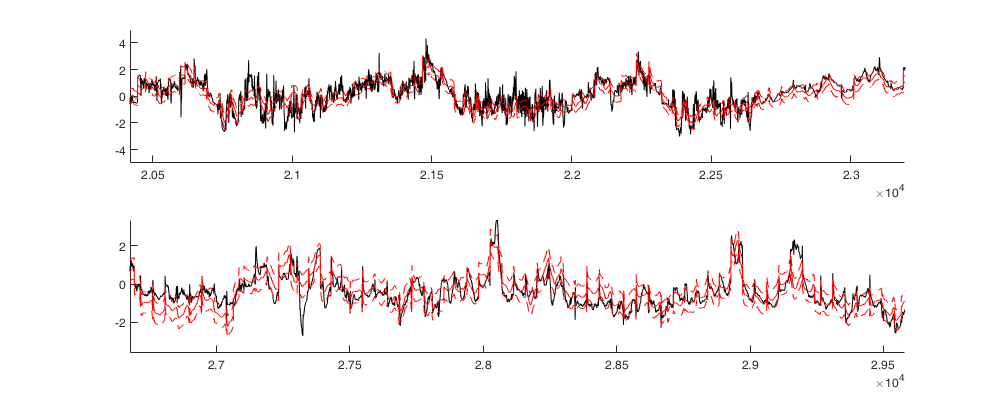

figure('position',[0 0 1000 400]); 
subplot(2,1,1); hold on;
plot(uv.ut,'k');
plot(ccuv.ut_est,'r');
plot(ccuv.ut_est-ccuv.ut_sig,'--r')
plot(ccuv.ut_est+ccuv.ut_sig,'--r')

subplot(2,1,2); hold on;
plot(uv.vt,'k');
plot(ccuv.vt_est,'r');
plot(ccuv.vt_est-ccuv.vt_sig,'--r')
plot(ccuv.vt_est+ccuv.vt_sig,'--r')

Normalized Error of Estimation (NEE)

nee_u = (ccuv.ut_est-uv.ut)./(ccuv.ut_sig);
nee_v = (ccuv.vt_est-uv.vt)./(ccuv.vt_sig);

Figure;

figure('position',[0 0 1000 400]); hold on;  
histogram( nee_u  ,'Normalization','pdf'); 
histogram( nee_v  ,'Normalization','pdf');
plot(-4:.1:4,normpdf(-4:.1:4),'linewidth',2)
legend(['Normalized error of kriging: mean=' num2str(nanmean(nee_u)) ' and std=' num2str(nanstd(nee_u))], ['Normalized error of kriging: mean=' num2str(nanmean(nee_v)) ' and std=' num2str(nanstd(nee_v))]);

Map of normalized error of estimation per radar

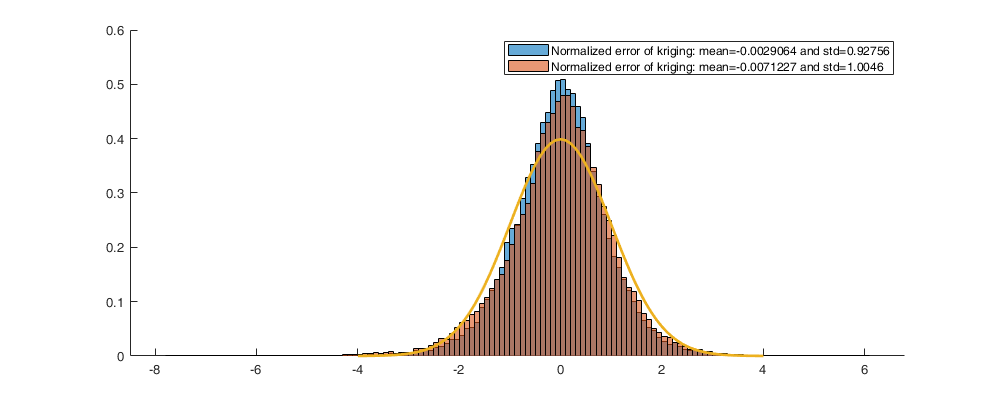

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lat],[dc.lon],splitapply(@std,nee_u,data.radar)*200,splitapply(@mean,nee_u,data.radar),'filled','MarkerEdgeColor','k'); 

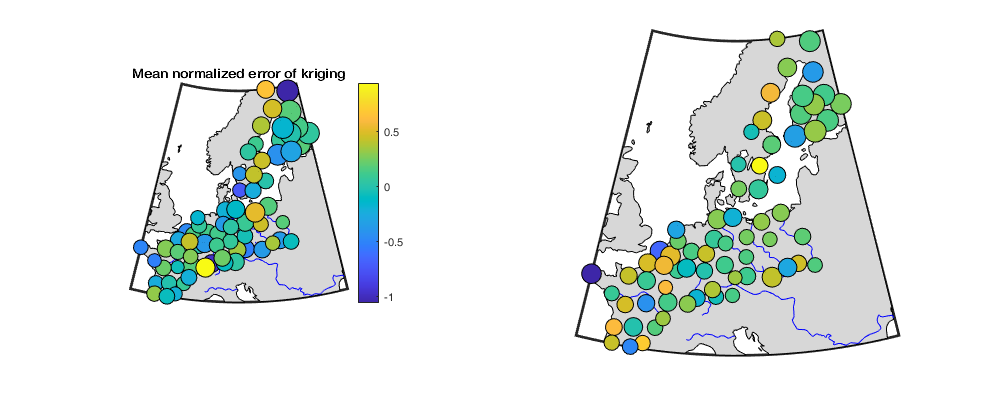

title('Mean normalized error of kriging'); colorbar;
subplot(1,2,2); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lat],[dc.lon],splitapply(@std,nee_v,data.radar)*200,splitapply(@mean,nee_v,data.radar),'filled','MarkerEdgeColor','k'); 

## Save

save('data/Flight_cross_validation.mat','ccuv','-v7.3')